Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Donkey's solution (Section 11.5)

Volker Ziemann, 211116, CC-BY-SA-4.0

In Section 11.5 we solve the **optimal-control problem** to find the best speed profile for the donkey to pull a mass for some distance `L` in a given time `T `across rough ground with friction constant $\alpha$, while minimizing the expended power, given by the pulling force squared. 

In the first part of the simulation we select the friction constant $\alpha$, the distance` L `and the given time `T.`

alpha=1.1   % friction constant

alpha = 1.1000

L=100;       % distance to cover in [m]
T=20;        % time for the travel in [s]
aT=alpha*T;

The difficult part of some optimal-control problems is that both initial and final boundary conditions are specified, which often requires solving implicit equations. But in linear problems solving is possible by carfeully solving a succession of linear equations. This derivation is explicitely done in Section 11.5, and here we immediately jump to Equation 11.49, which give us intergration constants `C3` and `C4` that we use to find `C1` and `C2` from the equations given in the text just before Equation 11.49.

y=[L;0];
A=[(exp(aT)-exp(-aT)-2*aT)/alpha , 1+aT-exp(aT);
  (exp(-aT)+exp(aT)-2)/alpha , 1-exp(aT)];
x=A\y; C3=x(1); C4=x(2);
C1=2*alpha^2*C3-alpha^3*C4;
C2=alpha^2*C4;

With the integration constants available we can define anonymous functions to describe the position $x_1$ of the donkey with Equation 11.47 and its speed $x_2$ by Equation 11.46, which are directly coded here.

x1=@(t)C4-(C3/alpha)*exp(-alpha*t)-(C1/alpha^2)*t ...
    -(1/(2*alpha^2))*(C2-C1/alpha)*exp(alpha*t); 
x2=@(t)C3*exp(-alpha*t)-C1/alpha^2-(1/(2*alpha))*(C2-C1/alpha)*exp(alpha*t);

Finally we plot both the donkey's position and speed for the duration of the travel.

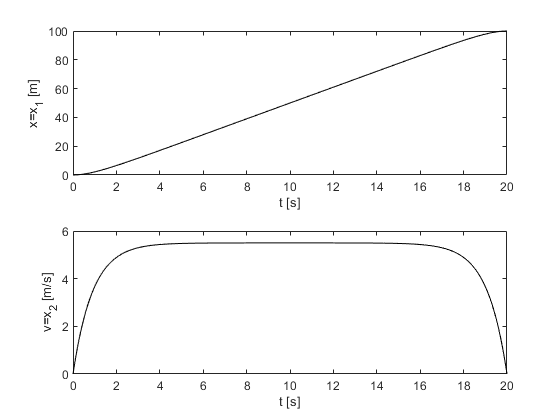

t=0:0.1:T;
subplot(2,1,1); plot(t,x1(t),'k')
xlabel('t [s]'); ylabel('x=x_1 [m]');
subplot(2,1,2); plot(t,x2(t),'k')
xlabel('t [s]'); ylabel('v=x_2 [m/s]');

Now play with the slider for the friction $\alpha$ and observe how the profile changes. If $\alpha$ is small, say $\alpha=0.1$, the donkey prefers a somewhat higher speed and a long acceleration to the half-way point. With larger friction, say $\alpha=1$,  the donkey early accelerates to its "cruising speed" and stays there until close to its arrival time.